clc;
close all;
clear;

Storage =dir(fullfile("D:","Eng","Image-Despeckling","Testset","speckled","*.png"));
fprintf("No.of images in the speckled set: %d\n",numel(Storage));

No.of images in the speckled set: 348



Noisy_set  = "D:\Eng\Image-Despeckling\Noisy_Dataset_train\";
Clean_set =  "D:\Eng\Image-Despeckling\Dataset_train\";
Testset_noisy = "D:\Eng\Image-Despeckling\Testset\speckled";
Testset_clean = "D:\Eng\Image-Despeckling\Testset\cleaned";


input = imread("D:\Eng\Image-Despeckling\Testset\speckled\speckled120.png");
input_img = im2gray(input);

I_hsv = rgb2hsv(input);
hueval = 10*mean(mean(I_hsv(:,:,1))); 
satval = 10*mean(mean(I_hsv(:,:,2)));
valval = 10*mean(mean(I_hsv(:,:,3))); % extracting hsv features of the image for it to act as a unique image signature

hueval = round(hueval,1);
satval = round(satval,1);
valval = round(valval,1);

hueval = uint8(hueval);
satval = uint8(satval);
valval = uint8(valval);

% file_to_read = fopen('speckled_vals.txt','r');
% A = fscanf(file_to_read,formatSpec);
% B = readtable('speckled_vals.txt','ReadVariableNames',true);
% B.Properties.VariableNames = {'Hue','Sat','Val'}; %This step writes all the hsv values in a text file 

% hue_val = (B(1,"Hue"));
% sat_val = (B(1,"Sat"));
% val_val = (B(1,"Val"));

% hue_val = table2array(hue_val);
% sat_val = table2array(sat_val);
% val_val = table2array(val_val);

formatSpec = '%d';
hsv_inputs = fopen("hsv_inputs.txt",'w');
fprintf(hsv_inputs,formatSpec,hueval,satval,valval); % writing hsv inputs to a buffer file 
disp("HSV values written...");

HSV values written...


pred_file = fopen('predicted_kernel.txt','r');
kernel_val_predicted = uint8(fscanf(pred_file,"%d"));
kernel_val_predicted = double(kernel_val_predicted)

kernel_val_predicted = 5

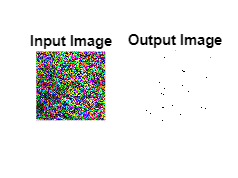

output_img = Leefilter(input_img,kernel_val_predicted); % despeckling using the predicted kernel value

output_img = postpr(output_img);
figure;
subplot(1,2,1);
imshow(input);
title("Input Image");
subplot(1,2,2);
imshow(output_img);
title("Output Image")


CleanLocation = fullfile(Testset_clean,sprintf('output88.png'));
imwrite(output_img,CleanLocation);

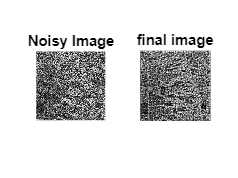

% outputs for the bilateral filter 
sigma_d = 1;       % Spatial standard deviation
sigma_r = 20;      % Intensity standard deviation
filter_size = 5;   % Filter size

denoised_image = bilateral_filter(input_img, sigma_d, sigma_r, filter_size);
dn = uint8(denoised_image);
final_image = postpr(dn);

% Display the results
subplot(1, 2, 1);
imshow(input_img);
title('Noisy Image');

subplot(1,2,2)
imshow(final_image)
title("final image")

% output of frost filter 
im_fi = frost_filter(input_img,[5,5],0.1)

im_fi =    49.0853   58.2988   65.4454   63.1030   54.2657   46.8599   42.5802   45.3413   46.7822   59.0243   60.7540   65.0900   67.5733   63.3140   55.2500   59.7874   65.6342   64.4043   73.9944   73.0880   64.1963   60.2780   61.1018   52.4652   61.2786   66.3824   70.2141   66.5748   72.0945   66.0479   80.9814   82.2425   82.1651   82.8075   86.2649   77.3943   80.2839   87.2194   89.5158   89.2092   84.4508   81.0364   77.9239   70.8146   67.0249   65.0223   54.9670   51.9523   46.0396   42.6365
   64.1623   78.8040   87.7296   82.3545   75.2340   69.4020   61.6682   66.5882   69.5839   80.5181   82.9805   85.9543   91.2618   87.8274   82.3090   89.9973  100.0070   97.3197  104.4556  104.2418   95.0517   87.2990   90.0135   78.1229   82.7254   90.5762   95.6096   84.1545   93.9246   89.9262  105.5725  108.7681  112.7388  118.0463  117.3597  103.3301  107.5864  113.2201  108.4254  106.4001   99.7627   94.1031   90.4470   85.5762   82.9664   87.3106   78.6620   74.7298   64.8450 

final = postpr(im_fi)

final =    17.5266   39.5641   60.8286   55.6133   41.0360   25.3295   14.7595   14.0804   19.9582   29.8968   37.3991   41.4284   39.1432   33.2753   28.6239   29.8576   36.5636   43.3348   46.8222   43.0511   34.5945   22.6054   14.1541    9.6715   13.4866   18.2188   23.0349   21.5642   23.7409   28.2475   39.0479   47.2729   53.4579   53.1807   49.2170   44.4515   44.5724   48.9282   51.8569   50.3316   44.2745   37.6377   30.8537   26.5492   22.7834   19.6771   12.0181    3.5034   -7.3929  -13.5435
   39.8825   83.4431  121.9028  116.5121   95.8452   72.6081   56.2530   53.7449   60.7271   73.4257   83.2414   89.1935   87.6150   81.7753   78.5485   85.1985  100.0943  114.3188  121.8535  117.2032  103.8177   83.2307   66.7653   56.2847   59.7505   65.3414   71.5713   68.4191   71.9213   80.2716   98.9611  114.2971  125.4349  125.5412  117.7947  108.8267  107.2299  112.7770  115.3714  110.8424   98.7878   86.8694   75.9650   71.1052   67.6586   65.9907   56.0893   44.7021   27.8552 

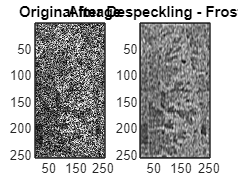


figure

subplot(1,2,1)
imagesc(input_img);
colormap(gray);
title('Original Image');

subplot(1,2,2)
imagesc(final);
colormap(gray);
title('After Despeckling - Frost Filter');

function lee_output = Leefilter(img,window_size)

img = double(img);
lee_output = img;
means = imfilter(img, fspecial('average', window_size), 'replicate');
sigmas = sqrt((img-means).^2/window_size^2);
sigmas = imfilter(sigmas, fspecial('average', window_size), 'replicate');

ENLs = (means./sigmas).^2;
sx2s = ((ENLs.*(sigmas).^2) - means.^2)./(ENLs + 1);
fbar = means + (sx2s.*(img-means)./(sx2s + (means.^2 ./ENLs)));
lee_output(means~=0) = fbar(means~=0);

end

function post_out = postpr(a)
    mf = ones(3, 3)/9;
    meanfilt = imfilter(a,mf);
    c =imsharpen(meanfilt,'Radius',3.5,'Amount',3.5);
    post_out = imfilter(c,mf);
end

function img_fi = frost_filter(img_n, win_size, Damp_fact)
    img_n = double(img_n);
    %Preallocate the Output Matrix
    img_fi = zeros(size(img_n));
    
    % making the window size odd if even
    if(mod(win_size,2)~=1)
        win_size=win_size+~mod(win_size,2);
    end
    
    mn = round((win_size-1)/2);
    
    %Padding with zeros around the border
    EImg = padarray(img_n,mn);
    
    
    [x,y]= meshgrid(-mn(1,1):mn(1,1),-mn(1,2):mn(1,2));
    S = sqrt(x.^2+y.^2);
    
    for i = 1:size(img_n,1)
        for j = 1:size(img_n,2)
            %Local Window
            K = EImg(i:i+win_size(1,1)-1,j:j+win_size(1,2)-1);
           
            %Mean value of the pixels in the local window
            meanV = mean(K(:));
           
            %variance of the pixels in the local window
            varV = var(K(:),1);
           
            %Weight for each pixel in the local window
            B =  Damp_fact*(varV/(meanV*meanV));
            Weigh = exp(-S.*B);
           
            % Filtering  
            img_fi(i,j) = sum(K(:).*Weigh(:))./sum(Weigh(:));
           
        end
    end

end


function denoised_image = bilateral_filter(image, sigma_d, sigma_r, filter_size)
    % Convert image to double precision
    image = double(image);
    
    % Create filter indices
    indices = -floor(filter_size/2):floor(filter_size/2);
    [X, Y] = meshgrid(indices, indices);
    
    % Compute the spatial Gaussian component
    G_spatial = exp(-(X.^2 + Y.^2) / (2 * sigma_d^2));
    
    % Initialize the denoised image
    denoised_image = zeros(size(image));
    
    % Iterate over the image
    [rows, cols] = size(image);
    for i = 1:rows
        for j = 1:cols
            % Extract the local region
            i_min = max(i - floor(filter_size/2), 1);
            i_max = min(i + floor(filter_size/2), rows);
            j_min = max(j - floor(filter_size/2), 1);
            j_max = min(j + floor(filter_size/2), cols);
            
            region = image(i_min:i_max, j_min:j_max);
            
            % Compute the intensity Gaussian component
            G_intensity = exp(-(region - image(i, j)).^2 / (2 * sigma_r^2));
            
            % Compute the bilateral filter response
            G_bilateral = G_spatial((i_min:i_max) - i + floor(filter_size/2) + 1, (j_min:j_max) - j + floor(filter_size/2) + 1) .* G_intensity;
            F_bilateral = G_bilateral .* region;
            
            % Update the denoised image
            denoised_image(i, j) = sum(F_bilateral(:)) / sum(G_bilateral(:));
        end
    end
    
    % Convert the denoised image back to the original data type
    denoised_image = cast(denoised_image, class(image));
end




